 %  Copyright 2021 University of Padua, Italy
 %
 %  Licensed under the Apache License, Version 2.0 (the "License");
 %  you may not use this file except in compliance with the License.
 %  You may obtain a copy of the License at
 %
 %       http://www.apache.org/licenses/LICENSE-2.0
 %
 %  Unless required by applicable law or agreed to in writing, software
 %  distributed under the License is distributed on an "AS IS" BASIS,
 %  WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied.
 %  See the License for the specific language governing permissions and
 %  limitations under the License.
 %
 % 
 % @author Nicola Ferro

# Computation of (Paired) Student's t test on TREC 08, 1999, AdHoc

This example shows how to compare runs from TREC 08, 1999, AdHoc using the Student's t test.

## Setup

Load the performance score about the runs. The file contains:

- `ap` (or another measure name): a matrix where rows are topics and columns are runs; each cell contains the AP score for a run on a given topic;

- `runs`: an array of strings containing the identifiers of the runs; elements in the array are in the same order as columns on ap;

- `topics`: an array of strings containing the identifiers of the topics; elements in the array are in the same order as rows on ap;

% Load Average Precision data
% Other measures available are: P@10, nDCG, RBP
%load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\FERROM\frrncl-T08\frrncl-se-unipd-350adedfc86d\hypothesis-testing\data\T08\ap.mat

% rename ap into measure to make follow-up processing the same for whatever
% measure we load
%measures = ap;

% remove the now useless ap matrix
%clear ap;

## Box Plot

Show the box plot of the runs.

% Compute the mean performance of each run across topics
% This is the MAP for each run, if we loaded the AP data
m_ndcg5 = mean(measure_ndcg5);

myruns4 = 1×5 string array
    "run1"    "run2"    "run3"    "run4"    "run5"


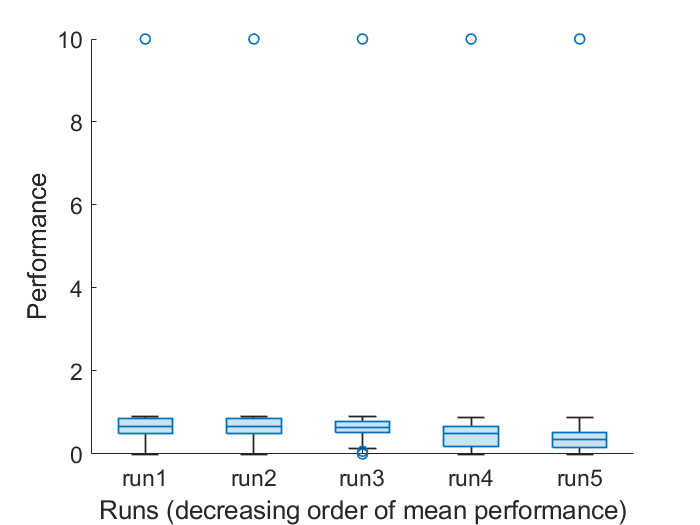

myruns4 = ogmyruns

% sort in descending order of mean score
[~, idx] = sort(m_ndcg5, 'descend');

% re-order runs by descending mean of the measure
% needed to have a more nice looking box plot
measure_ndcg5 = measure_ndcg5(:, idx);
myruns4 = myruns4(idx);

figure

% show the box plot
boxchart(measure_ndcg5)

%hold on

% plot the mean on top of the box plot
%plot (m, ':x', "MarkerSize", 10, "LineWidth", 2)

% adjust tick labels on x-axis, y-axis range, and font size
ax = gca;
ax.FontSize = 14;
ax.XTickLabel = myruns4;

xlabel("Runs (decreasing order of mean performance)")

ylabel("Performance")

## Student's t test

Compute the Student's t test between two runs

% the indexes of the two runs to compare
r1 = 2;
r2 = 5;

[~, p] = ttest(measure_ndcg5(:, r1), measure_ndcg5(:, r2))

p = 0.0075

fprintf("Run %s vs %s: p-value %f", myruns4(r1), myruns4(r2), p)

Run run2 vs run5: p-value 0.007512